การคำนวณหาค่า Q ที่สถานี S1 จากค่า H ระหว่าง Day 56 และ Day 60

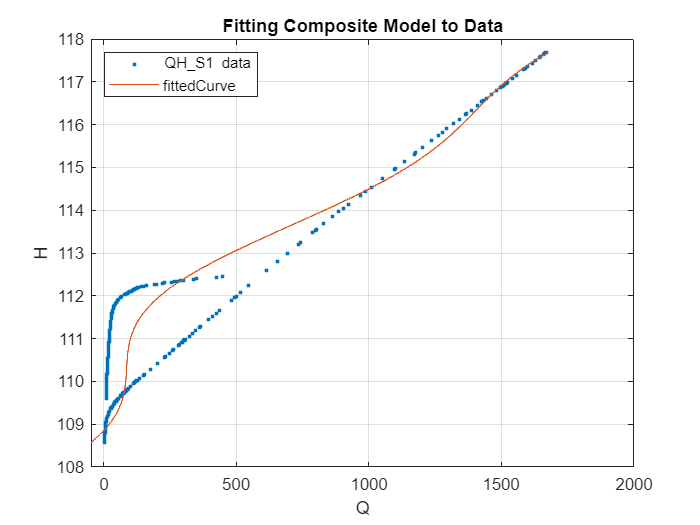

mdl = fittype('a*cos(x+f) + b*x^2 +c*x + d*log(x) + e','coefficients',{'a','b','c','d','e','f'},'independent','x','dependent','y');
fitResult = fit(HS1,QS1,mdl,"StartPoint",[0,0,0,0,0,1]);
coeffs = coeffvalues(fitResult);
a = coeffs(1);
b = coeffs(2);
c = coeffs(3);
d = coeffs(4);
e = coeffs(5);
f = coeffs(6);
nv = a * cos(HS1+f) + b * HS1.^2 + c*HS1 +d * log(HS1) + e;

plot(QS1,HS1,'.')
hold on
plot(nv,HS1)
hold off
grid on
xlabel('Q');
ylabel('H');
title('Fitting Composite Model to Data');
legend({'QH\_S1 data','fittedCurve'},'Location','northwest');

Performance ของการ Fitting

R_squared = 1 - sum((QS1 - nv).^2) / sum((QS1 - mean(QS1)).^2);
MAE = sum(abs(QS1 - nv))/length(QS1);
MSE = (sum((QS1 - nv).^2))/(length(QS1));
fprintf('R_squared = %f\nMAE = %f\nMSE = %f', R_squared,MAE,MSE);

R_squared = 0.967410
MAE = 65.357442
MSE = 9148.282583

Predict และแสดงค่า Q ของสถานี S1

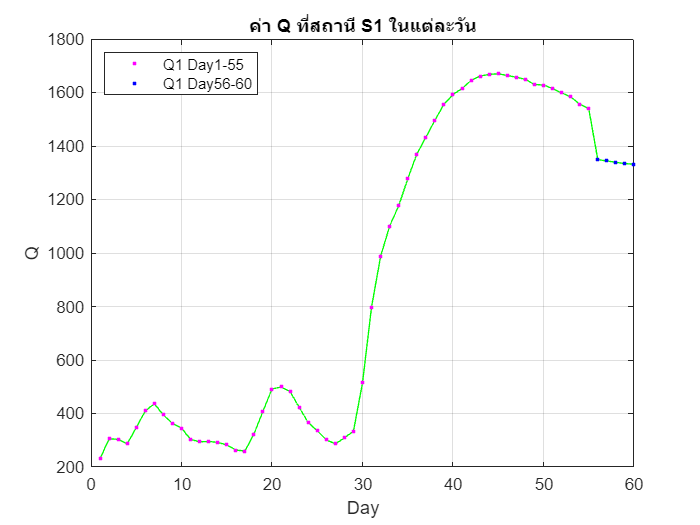

pdQ1 = a*cos(H1(56:60)+f) + b * H1(56:60).^2 + c*H1(56:60) +d * log(H1(56:60)) + e;
Q1 = [Q1(1:55);pdQ1];

plot(1:60,Q1,'g')
hold on
plot(1:55,Q1(1:55),'m.')
plot(56:60,Q1(56:60),'b.')
hold off
grid on
xlabel('Day');
ylabel('Q');
title('ค่า Q ที่สถานี S1 ในแต่ละวัน');
legend({'','Q1 Day1-55','Q1 Day56-60'},'Location','northwest');

fprintf('Day56: %.2f\nDay57: %.2f\nDay58: %.2f\nDay59: %.2f\nDay60: %.2f', Q1(56),Q1(57),Q1(58),Q1(59),Q1(60));

Day56: 1349.13
Day57: 1344.15
Day58: 1339.12
Day59: 1334.04
Day60: 1332.33